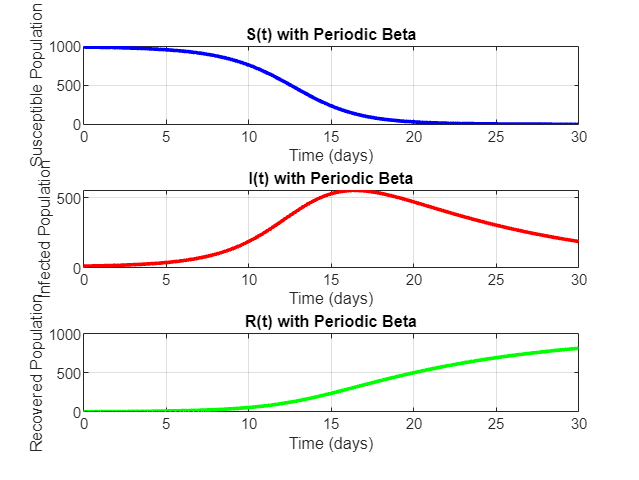

clear;
clc;

% Parameters
beta0 = 0.3;  % Base transmission rate
A = 5;        % Amplitude
omega_1 = 2*pi/365;  % Frequency for 1 day periodicity
omega_2 = 2*pi*100/365;  % Frequency for ~3 days periodicity
gamma = 0.1;  % Recovery rate
S0 = 990;     % Initial susceptible population
I0 = 10;      % Initial infected population
R0 = 0;       % Initial recovered population
N = 1000;     % Total population
T = 30;       % Total time (days)
h = 0.1;      % Time step (days)

% Time vector
t = 0:h:T;

% Run SIR model with omega = omega_1
[S1, I1, R1] = run_sir_with_periodic_beta(t, beta0, A, omega_1, gamma, S0, I0, R0, N);

% Plot S(t), I(t), and R(t)
figure;
subplot(3,1,1);
plot(t, S1, 'b', 'LineWidth', 2);
title('S(t) with Periodic Beta');
xlabel('Time (days)');
ylabel('Susceptible Population');
grid on;

subplot(3,1,2);
plot(t, I1, 'r', 'LineWidth', 2);
title('I(t) with Periodic Beta');
xlabel('Time (days)');
ylabel('Infected Population');
grid on;

subplot(3,1,3);
plot(t, R1, 'g', 'LineWidth', 2);
title('R(t) with Periodic Beta');
xlabel('Time (days)');
ylabel('Recovered Population');
grid on;


% Apply FFT to I(t) to get the spectrum
I_fft = fft(I1);
N_samples = length(I1);
f = (1/T) * (0:N_samples/2);  % Frequency vector
I_spectrum = abs(I_fft(1:N_samples/2+1));  % Half-spectrum

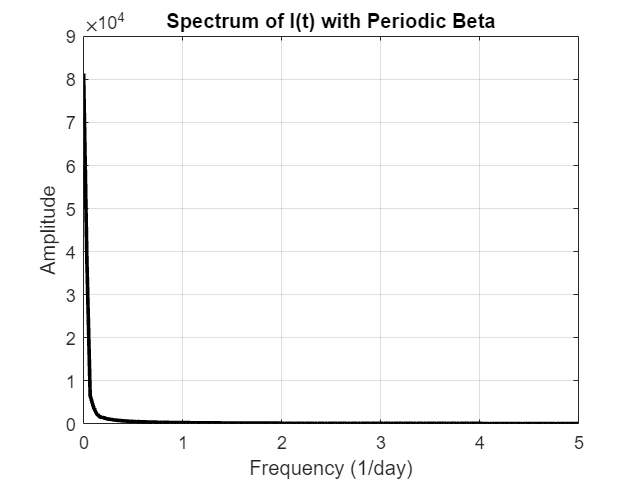


% Plot the spectrum for I(t)
figure;
plot(f, I_spectrum, 'k', 'LineWidth', 2);
title('Spectrum of I(t) with Periodic Beta');
xlabel('Frequency (1/day)');
ylabel('Amplitude');
grid on;

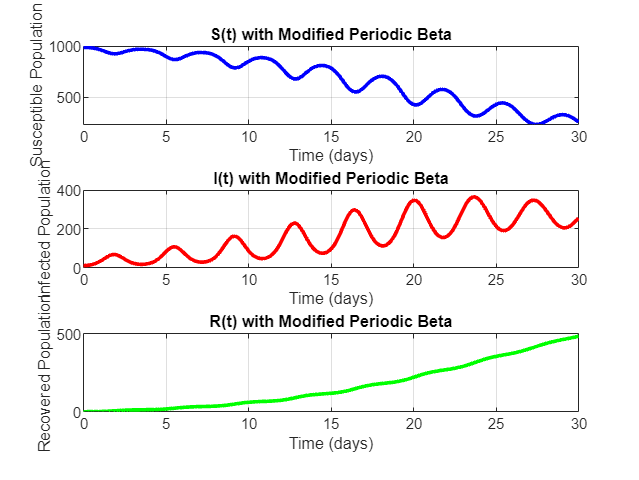


% Run SIR model with omega = omega_2 (modified periodicity)
[S2, I2, R2] = run_sir_with_periodic_beta(t, beta0, A, omega_2, gamma, S0, I0, R0, N);

% Plot S(t), I(t), and R(t) for omega_2
figure;
subplot(3,1,1);
plot(t, S2, 'b', 'LineWidth', 2);
title('S(t) with Modified Periodic Beta');
xlabel('Time (days)');
ylabel('Susceptible Population');
grid on;

subplot(3,1,2);
plot(t, I2, 'r', 'LineWidth', 2);
title('I(t) with Modified Periodic Beta');
xlabel('Time (days)');
ylabel('Infected Population');
grid on;

subplot(3,1,3);
plot(t, R2, 'g', 'LineWidth', 2);
title('R(t) with Modified Periodic Beta');
xlabel('Time (days)');
ylabel('Recovered Population');
grid on;


% Apply FFT to I(t) with modified omega to get the spectrum
I_fft2 = fft(I2);
I_spectrum2 = abs(I_fft2(1:N_samples/2+1));  % Half-spectrum

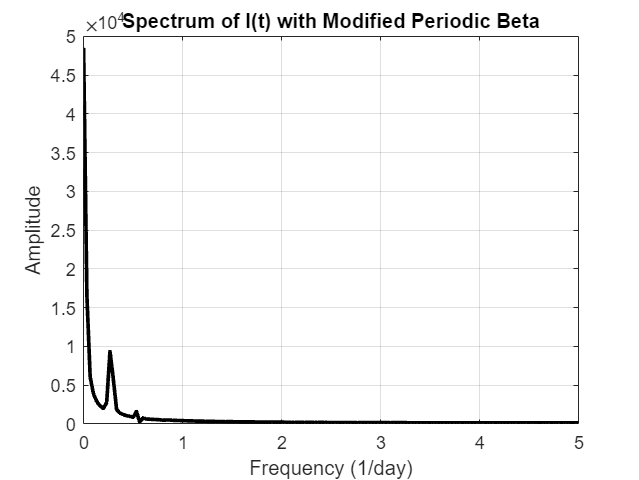


% Plot the spectrum for I(t) with modified omega
figure;
plot(f, I_spectrum2, 'k', 'LineWidth', 2);
title('Spectrum of I(t) with Modified Periodic Beta');
xlabel('Frequency (1/day)');
ylabel('Amplitude');
grid on;


% Function to compute the SIR model with time-varying beta

function [S, I, R] = run_sir_with_periodic_beta(t, beta0, A, omega, gamma, S0, I0, R0, N)
    % Initialize variables
    S = zeros(size(t));
    I = zeros(size(t));
    R = zeros(size(t));
    S(1) = S0;
    I(1) = I0;
    R(1) = R0;
    h = 0.1;
    % Run SIR model with periodic beta
    for i = 2:length(t)
        beta_t = beta0 * (1 + A * sin(omega * t(i)));  % Beta at time t(i)
        dS = -beta_t * S(i-1) * I(i-1) / N;
        dI = beta_t * S(i-1) * I(i-1) / N - gamma * I(i-1);
        dR = gamma * I(i-1);

        S(i) = S(i-1) + dS * h;
        I(i) = I(i-1) + dI * h;
        R(i) = R(i-1) + dR * h;
    end
end